# New Visualization and Path Display

This documentation tries to give good instructions on how to implement the new visualization and the path plotting together with the binary occupancy grid.

The Folder "NewGridVisualization" should include following functions:

    generateBOGriud.m

    generateMapVisual.m

    GridLocation.m

    GridMap.m

    plotPath.m

Those functions and classes can be moved later on to other folders.

To search inside the bog, use the VehiclePathPlanner_GridAStar class.

## Run everything

### Run visualization

To get it running,* replace* **Line 43** in **prepare_simulator** with the following

%Map = Map(mapName,waypoints, connections_circle,connections_translation, startingNodes, breakingNodes, stoppingNodes, leavingNodes);
Map = GridMap(mapName,waypoints, connections_circle,connections_translation, startingNodes, breakingNodes, stoppingNodes, leavingNodes);

### Run binary occupancy grid creation

To create the binary occupancy grid, the vehicles are needed to get their speed.

Because they are created after the Map, we have to add on emore line.

*Add* at **Line 63** in **prepare_simulator** 

%create BOG
[Map.bogMap,Map.xOffset,Map.yOffset] = generateBOGrid(Map);

### Run path plotting

*Add* at **Line 44** in **prepare_simulator** 

%variables for visualization
pathPlot;

*Add* **Line 110** in **VehiclePathPlanner**

%comment this in if you want the visualization of the cars
            if mod(get_param(obj.modelName,'SimulationTime'),0.2) == 0 
                %plotting can decrease performance, so dont update to often
                delete(obj.pathPlot)
                obj.pathPlot = plotPath(obj.Map,obj.vehicle.pathInfo.path,obj.vehicle.id);               
            end

### Run gridAStar

*Replace *at **Line 89 **in **VehiclePathPlanner**

%FuturePlan = obj.findNextRoute(obj.vehicle, obj.vehicle.pathInfo.lastWaypoint, obj.vehicle.pathInfo.destinationPoint,get_param(obj.modelName,'SimulationTime'),OtherVehiclesFutureData);
[FuturePlan,obj] = gridAStar(obj,get_param(obj.modelName,'SimulationTime'),OtherVehiclesFutureData);

*Add *at **Line 40 **in **VehiclePathPlanner**

%variables for gridA*
tempGoalNode;

Change output size of **VehiclePathPlanner** ([2000,6]) and **VehicleCommunication_v2v **([8000,6]) in the **getOutputSizeImpl()** function to fit nthe needed size of gridA* 

## Explanation

### Visualization in general

The new visualization consits of mainly two parta. First part is the creation and plot of the map, the second part is the path plotting of every vehicle.

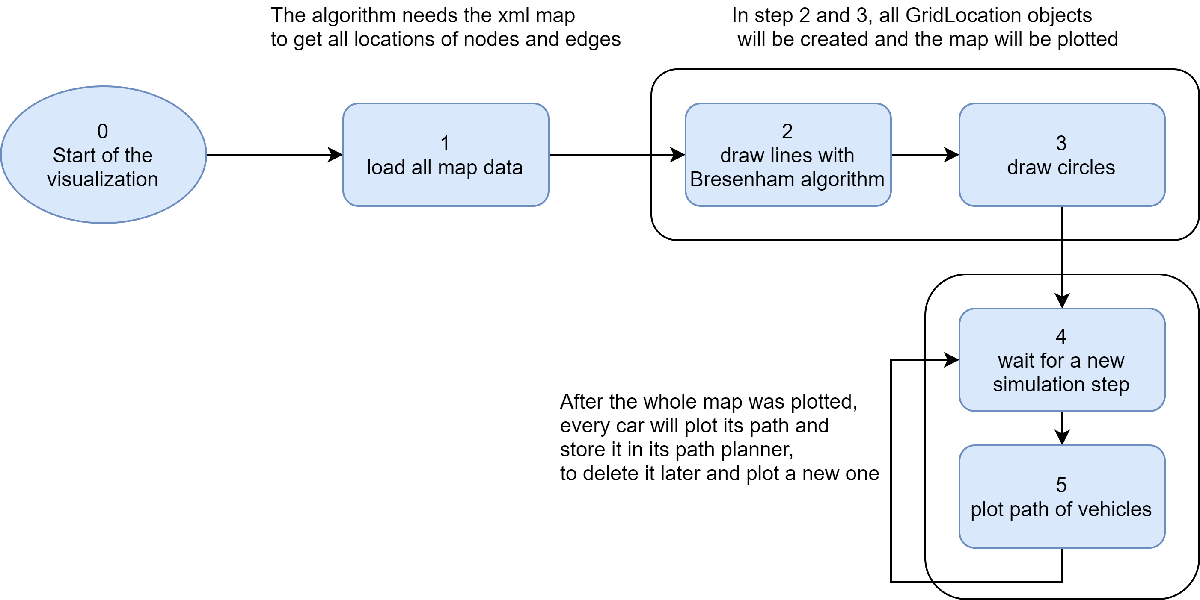

In step 1, all needed data will be gathered. To be able to create a grid and plot everything at the right place, all matrices of the graph, that contain information of the location and orientation of nodes and edges are needed. 

Step 2 and 3 will plot the map in figure 2. This plot will stay in place, everything else will be altered later. The cars are displayed as scatters and will be moved within the infrastructure class. The map plot is created inside the GridMap constructor

In step 4 and 5 every path is stored inside the VehiclePathPlanner class of its vehicle. It will be deleted and redrawn in every simulation step.

The bog map will be created seperately inside the prepare_simulator script.

### Visualization Example

Please only run this section and return to it after going through the generateMapVisual and plotPath function to see the plot here below.

figure
%create struct as substitute for map
map = struct;

%                       x  z     y  Node
map.waypoints = [   0  0     0; %1
                      200  0     0; %2
                      200  0  -200; %3
                        0  0  -200];%4
                    
%                            start  goal  angle   x z y   speed
map.connections.circle = [ 2     3      pi  200 0 -100 20;
                           4     1      pi    0 0 -100 20];
%                                 start goal speed                       
map.connections.translation = [ 1     2   20;
                                3     4   20];

displayInGridCoordinates = false;
generateMapVisual(map,displayInGridCoordinates);
%please only run until after the generateMapVisual function and return to
%here to see the plot

%plot path
carID = 1;
path = [1 2 3];
map.Vehicles(1).dynamics.position = [0 0 0];%the algorithm needs to know the current vehicle location

pathPlot = plotPath(map,path,carID);

pathPlot =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×34 double]
              YData: [1×34 double]
              ZData: [1×0 double]

  Show all properties


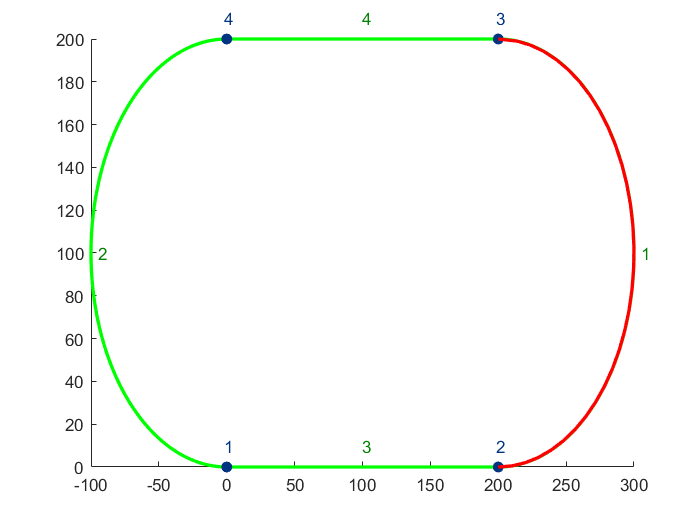


delete(pathPlot);
map.Vehicles(1).dynamics.position = [200 0 0];
path = [2 3];
pathPlot = plotPath(map,path,carID);

## GridMap 

[go back to the Table of Content]

The GridMap is equal to the Map, but it uses a normal plot, instead of a graph plot and has also some more objects.

**Line 59 ** was replaced by the **implementMapVisual** function (now **Line 52**).

**Line 76-77** where deleted, because they altered the old graph plot

**Line 51-56 **where deleted, because they belonged to the graph plot.

**Line 77** added (make z coordinates)

obj.plots.Vehicles.ZData = 0.1 .* ones(1,10);

**Line 242** changed to (make z coordinates)

 allVehiclePositions = [allVehiclePositions(1:length(obj.Vehicles),1)-10, -allVehiclePositions(1:length(obj.Vehicles),3)+12, 0.2 .* ones(1,10)'];

## generateMapVisual()

[go back to the Table of Content]

The function generateMapVisual creates the map plot, to see where vehicles are going.

 function generateMapVisual(gridMap,displayInGridCoordinates)

Input:        map object, boolean = 1 if we want use grid coordinates istead of normal ones

Output: --

First we use hold on, to draw everything inside one plot. 

We also have to load every map information.

            hold on            
            w = gridMap.waypoints;
            circ = gridMap.connections.circle;
            trans = gridMap.connections.translation;
            %coordinate transformation
            w(:,3) = -1.*w(:,3);
            circ(:,6) = -1.*circ(:,6);
            

The function still has the option to switch to grid coordinates. This can not be used in the moment, because the cars would have to change to grid position as well in the plot, but could be used later on.

            if displayInGridCoordinates
                xOff = min(w(:,1))-50;  %TODO make it global later
                yOff = min(w(:,3))-50;  %offset should be global
                
                w(:,3) = w(:,3)-yOff;
                w(:,1) = w(:,1)-xOff;                
                
                circ(:,4) = circ(:,4)-xOff;
                circ(:,6) = circ(:,6)-yOff;
            end            

We start with the curved roads. For every curve we load the starting and ending point and calculate the angles in between. Then we calculate points on the circle with htis information and plot the curve.

            %% Generate a usable plot
            %% generate curves
            for c = 1 : size(circ,1)
                cPart = circ(c,:);
                %start
                x1 = w(cPart(1),1); 
                y1 = w(cPart(1),3);   
                %goal
                x2 = w(cPart(2),1); 
                y2 = w(cPart(2),3);
                %central point
                x0W = cPart(4); 
                y0W = cPart(6);
                %radius
                radius = norm( [x2,y2]-[x0W,y0W] );
                %angles
                phiStart = angle(complex((x1-x0W) , (y1-y0W)));
                phiGoal = angle(complex((x2-x0W) , (y2-y0W)));
                %direction
                direction = sign(cPart(3));
                %% make angle allways usable
                if phiStart <0
                    phiStart = phiStart + 2*3.1415;
                end
                if phiGoal <0
                    phiGoal = phiGoal + 2*3.1415;
                end
                %make turns through 0° possible
                if (direction == -1 && phiStart < phiGoal)
                    phiStart = phiStart + 2*3.1415;
                end
                if (direction == 1 && phiStart > phiGoal)
                    phiGoal = phiGoal + 2*3.1415;
                end

A vector with some angles is created to claculate points on the circle to plot later.

                phi1 = phiStart : direction*0.01 : phiGoal;
                phi1(1) = phiStart;
                phi1(length(phi1)) = phiGoal;
                points = [(radius .* cos(phi1)+x0W)',(radius .* sin(phi1))'+y0W];                

Now the whole circle is plotted.

                plot(points(:,1),points(:,2),'color',[0 1 0],'LineWidth',2);
                %plot number next to edge
                textPos = points(round(length(points)/2,0),:);                
                text(textPos(1)+5,textPos(2),num2str(c),'color',[0 0.5 0]);
            end

For the straight lines, we just need to plot a line between the start and the goal point.

We also add the number of the edge as a description.

            %% generate straight lines
            for t = 1 : size(trans,1)
                position = zeros(2,2);
                %get both points and plot a line in between
                position(1,:) = [w(trans(t,1),1) ,w(trans(t,1),3)];
                position(2,:) = [w(trans(t,2),1) ,w(trans(t,2),3)];
                plot(position(:,1),position(:,2),'color',[0 1 0],'LineWidth',2);
                %plot number next to edge
                textPos = (position(2,:) + position(1,:))/2;                
                text(textPos(1),textPos(2)+10,num2str(t+c),'color',[0 0.5 0]);
            end

The last thing would be, to plot the nodes with their number.

            %% plot nodes with numbers
            for n = 1 : length(w)
                pos = [w(n,1),w(n,3)];
                plot(pos(1),pos(2),'Marker','o','MarkerFaceColor',[0 0.2 0.5],'color',[0 0.2 0.5]);
                text(pos(1)-2,pos(2)+10,num2str(n),'color',[0 0.2 0.5]);%TODO make it appear automatically under dot
                %maybe there is a way to let it not collide with other text?
            end
            hold off
         end

[Back to plot]

## generateBOGrid()

[go back to the Table of Content]

This function generates the binary occupancy grid object and a GridLocation object for every cell of the bog.

            function [bogMap,xOff,yOff] = generateBOGrid(map)

Input: GridMap object

Output: the bog object, the x offset, the y offset of the bog map

First we start by importing every map data.

            %% prepare for drawing
            nrOfCars = length([map.Vehicles.id]); %comment in if you know
            %the number of cars            
            gSize = map.gridSize;
            %first we need map size
            %we can get it from waypoints with some space for better
            %display
            distances = map.connections.distances;
            w = map.waypoints;  %[x z y]
            w(:,3) = -1.*w(:,3);%transform to mobatsim coordinates

We need to determine the size of the map here.

            xSize = max(w(:,1))-min(w(:,1))+100;
            xOff = min(w(:,1))-50;            
            ySize = max(w(:,3))-min(w(:,3))+100;
            yOff = min(w(:,3))-50;

The speed limit has to be accurate for every vehicle.

            %calculate speedLimit [carID,edgeNR]
            maxEdgeSpeed = [map.connections.circle(:,end);map.connections.translation(:,end)];%TODO move to GridMap object and make it unique for every vehicle!
            speedLimit = zeros(nrOfCars,length(maxEdgeSpeed));
            for car = 1 : nrOfCars
                maxSpeed = map.Vehicles(car).dynamics.maxSpeed ;
                maxEdgeSpeed(maxEdgeSpeed>maxSpeed)= maxSpeed;
                speedLimit(car,:) = maxEdgeSpeed;
            end             

Now we can create the bog object and start with the map generation. The cars can only use the edges, so the rest has to be blocked.

            bogMap = binaryOccupancyMap(xSize,ySize,gSize);
            %mark everything as blocked
            occ = ones(ySize*gSize,xSize*gSize);
            setOccupancy(bogMap,[0,0],occ);%lower left corner to set values
            
            %import map details
            trans = map.connections.translation; %[from to speed]
            circ = map.connections.circle; %[from to angle xzyCenter speed]
            circ(:,6) = -1.*circ(:,6);

To create straight edges, we use the bresenham algorithm.

            %% bresenham algorithm
            for j = size(map.connections.all,1) :-1: (size(circ,1)+1) 
                t= j - size(circ,1);
                %j is nr for all, t only inside transitions
                dist = distances(j);
                %start node coordinates in grid
                p1 = bogMap.world2grid([w(trans(t,1),1)-xOff,w(trans(t,1),3)-yOff]);
                %end node coordinates in grid
                p2 = bogMap.world2grid([w(trans(t,2),1)-xOff,w(trans(t,2),3)-yOff]);
                %get difference
                deltaX = p2(1)-p1(1);
                delatY = p2(2)-p1(2);
                %get deistance and direction
                absDx = abs(deltaX);
                absDy = abs(delatY); % distance
                signDx = sign(deltaX);
                signDy = sign(delatY); % direction
                %determine which direction to go
                if absDx > absDy
                    % x is shorter
                    pdx = signDx;
                    pdy = 0;        %p is parallel
                    ddx = signDx;
                    ddy = signDy; % d is diagonal
                    deltaLongDirection  = absDy;
                    deltaShortDirection  = absDx;
                else
                    % y is shorter
                    pdx = 0;
                    pdy = signDy; % p is parallel
                    ddx = signDx;
                    ddy = signDy; % d is diagonal
                    deltaLongDirection  = absDx;
                    deltaShortDirection  = absDy;
                end
                %start at node 1
                x = p1(1);
                y = p1(2);                

We dont draw pixel here, but instead mark the grid cell as free and create a GridLocation object for it.

                setOccupancy(bogMap,[x,y],0,"grid");
                
                %create grid location================================= 
                startNodeNR = map.connections.all(j,1);
                endNodeNR = map.connections.all(j,2);
                curKey = append(num2str(x), ",", num2str(y));
                %if we dont have it -> create, else we import it
                if ~map.gridLocationMap.isKey(curKey)                
                    %if we dont have the gl in our map we need to add it
                    curGL = GridLocation([x,y],nrOfCars,startNodeNR,0);
                else
                    curGL = map.gridLocationMap(curKey);
                end
                pixelArray = [];
                %=====================================================                
                
                error = deltaShortDirection/2;
                
                %now set the pixel
                for i= 1:deltaShortDirection          
                    % for each pixel
                    % update error
                    error = error - deltaLongDirection;
                    if error < 0
                        error = error + deltaShortDirection; % error is never < 0
                        % go in long direction
                        x = x + ddx;
                        y = y + ddy; % diagonal
                    else
                        % go in short direction
                        x = x + pdx;
                        y = y + pdy; % parallel
                    end
                    setOccupancy(bogMap,[x,y],0,"grid");
                    %================={build grid}=======================                    

We can now go from pixel to pixel.

                    if i ~= deltaShortDirection                        
                        %create new GL
                        newKey = append(num2str(x), ",", num2str(y));                        
                        %create new key
                        if ~map.gridLocationMap.isKey(newKey)
                            newGL = GridLocation([x,y],nrOfCars,0,j);
                        else
                            newGL = map.gridLocationMap(newKey);
                        end

It is useful to assign the successors and predecessors right here, so that we can access them later in the search.

                        curGL = curGL.addTransSucc(newKey,startNodeNR);
                        newGL = newGL.addTransPred(curKey,endNodeNR);
                        %now we can add the old gl to the map                        
                        pixelArray = [pixelArray,curGL]; %#ok<*AGROW> 
                        %remember for next round
                        
                        curGL = newGL;
                        curKey = newKey;
                    else

The last pixel will be the node, so we treat it diferently. It has no successor on this edge.

                        %if we dont have the gl in our map we need to add it
                        newKey = append(num2str(x), ",", num2str(y));
                        if ~map.gridLocationMap.isKey(newKey)
                            %create new GL
                            newGL = GridLocation([x,y],nrOfCars,map.connections.all(j,2),0);
                        else
                            %if it already exist, we just update succs and preds
                            newGL = map.gridLocationMap(newKey);
                        end
                        %assign grid relation
                        curGL = curGL.addTransSucc(newKey,startNodeNR);
                        newGL = newGL.addTransPred(curKey,endNodeNR);
                        pixelArray = [pixelArray,curGL,newGL];
                    end
                    %=====================================================
                end 

The grid location also needs to get the right map information assigned.

                %now assign properties
                dist = dist/size(pixelArray,2);
                for pix = pixelArray
                    p = pix.assignDistance(dist);
                    p.speedLimit = speedLimit(:,j);
                    %assign to map
                    map.gridLocationMap(append(num2str(p.coordinates(1)), ",", num2str(pix.coordinates(2))))=p;
                end
            end

Now that we have plotted every straight edge, we need to plot the curves.

            %% draw a circle pixel by pixel
            for t = size(circ,1):-1:1
                
                dist = distances(t);
                pStart = bogMap.world2grid([w(circ(t,1),1)-xOff,w(circ(t,1),3)-yOff]); %start
                pGoal = bogMap.world2grid([w(circ(t,2),1)-xOff,w(circ(t,2),3)-yOff]); %goal
                pCenter = bogMap.world2grid([circ(t,4)-xOff,circ(t,6)-yOff]); %central point
                radius = round(norm( pGoal-pCenter  ),0);
                phiStart = angle(complex((pStart(1)-pCenter(1)) , (pStart(2)-pCenter(2))));
                phiGoal = angle(complex((pGoal(1)-pCenter(1)) , (pGoal(2)-pCenter(2))));
                direction = sign(circ(t,3));
                if phiStart <0
                    phiStart = phiStart + 2*3.1415;
                end
                if phiGoal <0
                    phiGoal = phiGoal + 2*3.1415;
                end
                offset = 0;
                %make turns through 0° possible
                if (direction == -1 && phiStart < phiGoal)
                    offset = 2*3.1415;
                    phiStart = phiStart + offset;
                end
                if (direction == 1 && phiStart > phiGoal)
                    offset = 2*3.1415;
                    phiGoal = phiGoal + offset;
                end                

To be able to connect every GridLocation on the fly, we need to draw the circle in the right direction step by step. For that we evaluate every neighbour of the last pixel and draw on the one, with the lowest distance to a point on the circle with the same angle.

                %calculate the next pixel
                curPix = pStart;
                pixelArray = [];
                pixelArray = [pixelArray,append(num2str(curPix(1)), ",", num2str(curPix(2)))];
                curPhi = phiStart;
                while curPix(1) ~= pGoal(1) || curPix(2) ~= pGoal(2)
                    nextPix = [];   %the next pixel to draw in grid
                    nextPhi = 0;

We use a high number in the beginning, to make sure that we get the first neighbour as default.

                    deltaR = 200000;     %distance to the radius point with angle phi
                    %for every neighbour
                    for x = -1 : 1
                        for y = -1 : 1
                            if x ~= 0 || y ~= 0
                                %compare pixel for the closest one to the original
                                %point
                                %calculate the distance between the pixel and the
                                %reference and use the closest
                                neighbourPix = [curPix(1)+x,curPix(2)+y];%new pixel in grid
                                phi = angle(complex((neighbourPix(1)-pCenter(1)) , (neighbourPix(2)-pCenter(2))));%angle in world
                                if phi < 0
                                    phi = phi + 2*3.1415;
                                else
                                    phi = phi + offset;
                                end

We only have to use the neighbours, that are between the start and the goal angle.

                                %test, if the angle is relevant
                                if (direction == 1 && curPhi <= phi && phiGoal >= phi)|| (direction ==-1 && curPhi >= phi && phiGoal <= phi)
                                    referencePoint = [radius * cos(phi)+pCenter(1),radius*sin(phi)+pCenter(2)];%reference in world
                                    refDeltaR = norm(neighbourPix - referencePoint);
                                    if refDeltaR < deltaR
                                        deltaR = refDeltaR;
                                        nextPix = neighbourPix;
                                        nextPhi = phi;
                                    end
                                end
                            end
                        end
                    end                    
                    curPix = nextPix;
                    curPhi = nextPhi;
                    %now curPix is the next pixel to draw

Here we just store the key, the location of the cell, and create everything later.

                    pixelArray = [pixelArray, append(num2str(curPix(1)), ",", num2str(curPix(2)))];
                end

After we have gathered every needed pixel, we can start creating the GridLoction objects.

                %now draw pixel and assign to map
                startNodeNR = map.connections.all(t,1);
                endNodeNR = map.connections.all(t,2);
                curKey = pixelArray(1);
                dist = dist/size(pixelArray,2);
                %load or create gl for starting node
                if ~map.gridLocationMap.isKey(curKey)
                    curGL = GridLocation(pStart,nrOfCars,map.connections.all(t,1),0);
                else
                    curGL = map.gridLocationMap(curKey);
                end
                curGL = curGL.assignDistance(dist);%assign distance
                curGL.speedLimit = speedLimit(:,t);
                p = str2num(pixelArray(1));
                setOccupancy(bogMap,p,0,"grid");%draw                

We assign pre- and successors.

                for s = 2 : (length(pixelArray)-1)   %start connecting                 
                    newKey = pixelArray(s);
                    p = str2num(newKey);
                    setOccupancy(bogMap,p,0,"grid");
                    %create new GL
                    if ~map.gridLocationMap.isKey(newKey)
                        newGL = GridLocation(p,nrOfCars,0,t);
                    else
                        %load
                        newGL = map.gridLocationMap(newKey);
                    end
                    newGL = newGL.assignDistance(dist);
                    curGL.speedLimit = speedLimit(:,t);
                    %assign succ
                    curGL = curGL.addTransSucc(newKey,startNodeNR);
                    newGL = newGL.addTransPred(curKey,endNodeNR);
                    map.gridLocationMap(curKey)=curGL;
                    curGL = newGL;
                    oldKey = curKey;
                    curKey = newKey;                    
                end
                %if we dont have the gl in our map we need to add it
                newKey = pixelArray(end);
                if ~map.gridLocationMap.isKey(newKey)
                    %create new
                    p = str2num(newKey);
                    newGL = GridLocation(p,nrOfCars,map.connections.all(t,2),0);
                else
                    %load
                    newGL = map.gridLocationMap(newKey);
                end
                setOccupancy(bogMap,p,0,"grid");
                p = str2num(oldKey);
                setOccupancy(bogMap,p,0,"grid");
                %assign grid relation               
                newGL = newGL.assignDistance(dist);
                newGL.speedLimit = speedLimit(:,t);
                curGL = curGL.addTransSucc(newKey,startNodeNR);
                newGL = newGL.addTransPred(curKey,endNodeNR);

Every GridLocation is stored inside the gridLocationMap container map.

                map.gridLocationMap(curKey)=curGL;
                map.gridLocationMap(newKey)=newGL;
            end            
         end

## GridLocation 

[go back to the Table of Content]

The class GridLocation is used to give every pixel inside the binary occupancy grid a unique object. In it relevant data can be stored.

TODO: The distance of a GL is not allways right, because a GL can be part of two different edges and would have to have two different distances to be accurate. I have not found a way to be able to store those distances in a way, where you can access it later correctly.

The properties store relevant data. They will be changed by the search.

        function propertiesOfGridLocationClass()     
        coordinates = [];       %[x,y]
        successors = [];        %[every GridLocation we can reach from this GL]
        predecessors = [];      %[every GL from which we can reach this GL]
        transMapSucc;           %key = start node of edge, value = successor key "x,y"
        transMapPred;           %key = end node of edge, value = predecessor key "x,y"
        gValue = 0;             % G value for search
        fValue = 0;             % F value for search
        nodeNR;                 % 0 = no node, NR of a node in graph
        edgeNR;                 % 0 = no edge, NR of edge it belongs
        distance=0;             %distance to get over the GL
        parent;                 %GL that came before this one on our path
        edgeStart;              %node nr of the start of the current edge
        totalDistance;          %distance travelled so far
        speedLimit = [];        %maximum speed on this GL
        deviation = 0;          %standard deviation
        blocked;                %true = blocked
        
        speedVector;            %the average speed of every vehicle on this GL
        timeVector;             %the estimated time a vehicle will arrive on this GL
        probabilityVector;      %standard deviation of each vehicle
    end

The constructor assigns the most relevant properties in the moment of the creation. We need to setup the container maps to store the keys for other grid locations later.  

    function obj = GridLocation(xy,nrOfCars,node,edge)
            %Construct an instance of this class
            obj.coordinates = xy;
            obj.nodeNR = node;
            obj.edgeNR = edge;
            obj.transMapSucc = containers.Map();
            obj.transMapPred = containers.Map();
            obj.parent = 0;
            obj.totalDistance = 0;
            obj.blocked = false;
            
            obj.speedVector = zeros(nrOfCars,1);
            obj.timeVector = zeros(nrOfCars,1);
            obj.probabilityVector = zeros(nrOfCars,1);
        end

The functions are mainly to assign data the right way to the properties. 

        function obj = addSucc(obj,succ)
            if isempty(obj.successors) || ~ismember(succ,obj.successors)
                obj.successors = [obj.successors,succ];
            end
        end
        function obj = addPred(obj,pred)
            if isempty(obj.predecessors) || ~ismember(pred,obj.predecessors)
                obj.predecessors = [obj.predecessors,pred];
            end
        end

To add successors and predecessors, we first need to check, if the GL is a node or a part of an edge. This is necessary, because nodes have just successors, but a part of an edge needs to know, where it came from, to get the right successor. Otherwise we could not determine the successors, if the same GL is part of two or more edges.

Also only add successors or predecessors, that are not already added.

        function obj = addTransSucc(obj,succ,startNodeNR)
            if obj.nodeNR ~= 0
                %if we are a node
                obj = obj.addSucc(succ);
            else
                %if we are a part of an edge
                if obj.transMapSucc.isKey(num2str(startNodeNR))
                    oldSucc = obj.transMapSucc(num2str(startNodeNR));
                    if ~ismember(succ,oldSucc)
                        obj.transMapSucc(num2str(startNodeNR))=[oldSucc,succ];
                    end
                else
                    obj.transMapSucc(num2str(startNodeNR))=succ;
                end
            end
        end
        function obj = addTransPred(obj,pred,endNodeNR)
            if obj.nodeNR ~= 0
                %if we are a node
                obj = obj.addPred(pred);
            else
                %if we are a part of an edge
                if obj.transMapPred.isKey(num2str(endNodeNR))
                    oldPred = obj.transMapPred(num2str(endNodeNR));
                    if ~ismember(pred,oldPred)
                        obj.transMapPred(num2str(endNodeNR))=[oldPred,pred];
                    end
                else
                    obj.transMapPred(num2str(endNodeNR))=pred;
                end
            end
        end

Because a GL can be part of more than one edge, we have to keep that in mind. Maybe in the future there could be a better way, because now we dont have allways the right distance.

        function obj = assignDistance(obj,newDistance)
            if obj.distance == 0
                obj.distance = newDistance;
            else
                obj.distance = (obj.distance + newDistance)/2;
            end
        end

## plotPath

[go back to the Table of Content]

The plot path function can be used, to plot the planned path of every vehicle.

Input: 

    map is the XML map object, 

    displayInGridCoordinates is a boolean: true = display grid, false = display normal plot

    carID is the ID of the Car that wnts to plot its path

Output:

    pathPlot is the plot of the path. We output it, to be able to delete it next turn to plot again.

TODO: maybe find a better wy than swithc case, to set the colour and plot the path.

function pathPlot = plotPath(map,path,carID)

To plot the path, we need to make hold on, to not delete the existing plot. We also load every important data. The colourMatrix stores every colour per vehicle. You can chnge the colour here or make it an input later, if needed.

    hold on
    colourMatrix = [1 0 0;                      %1  red
                    1 1 0 ;                     %2	yellow
                    0 1 1 ;                     %3  light blue
                    0 0.2470 0.5410;            %4  dark blue
                    0.8500 0.3250 0.0980;       %5  orange
                    1 0 1;                      %6  magenta
                    0 0.4470 0.7410;            %7  blue
                    0.6350 0.0780 0.1840;       %8  dark red
                    0.3 0.3 0.3;                %9  grey
                    0.4940 0.1840 0.5560;       %10 violet
                    ];
    w = map.waypoints;
    w(:,3) = -1.*w(:,3);
    circ = map.connections.circle;
    circ(:,6) = -1.*circ(:,6);
    trans = map.connections.translation;
    

These two vaiables can be used later on to draw with an offset, if needed.

    %use offset if you need it
    xOff = 0;
    yOff = 0;
    

Because we will plot a path, we can first just gather every point, and than plot. That makes it possible to plot everything together and get one plot object.

    %% plot path for every vehicle
    pathPlot = [];
    bogPath = [];%list of points to plot
    %determine if circle or not
    for k = 2 : size(path,2)
        p1 = path(k-1);
        p2 = path(k);
        straight = ~isempty(trans(trans(:,1) == p1 & trans(:,2) == p2,:));

We have to plot a straight and a curved path differently. bogPath is a vector with all points on the path. We add points to it and plot those later. We have to treat the first entry differently than the other ones

        if straight
            %just draw a line
            if isempty(bogPath)
                bogPath = [[map.Vehicles(carID).dynamics.position(1)-xOff,-map.Vehicles(carID).dynamics.position(3)-yOff]; [w(p2,1)-xOff,w(p2,3)-yOff]];
            else
                bogPath = [bogPath;[w(p1,1)-xOff,w(p1,3)-yOff]; [w(p2,1)-xOff,w(p2,3)-yOff]];
            end
        else

For the curves, we calculate some points between the start and goal angle.

            %gather points on the circle
            rad = circ( circ(:,1)==p1 & circ(:,2) == p2,:);
            if isempty(bogPath)
                x1 = map.Vehicles(carID).dynamics.position(1)-xOff;
                y1 = -map.Vehicles(carID).dynamics.position(3)-yOff;
            else
                x1 = w(rad(1),1)-xOff; %start
                y1 = w(rad(1),3)-yOff;
            end
            x2 = w(rad(2),1)-xOff; %goal
            y2 = w(rad(2),3)-yOff;
            x0W = rad(4)-xOff; %central point
            y0W = rad(6)-yOff;
            radius = norm( [x2,y2]-[x0W,y0W] );
            phiStart = angle(complex((x1-x0W) , (y1-y0W)));
            phiGoal = angle(complex((x2-x0W) , (y2-y0W)));
            direction = sign(rad(3));
            if phiStart <0
                phiStart = phiStart + 2*3.1415;
            end
            if phiGoal <0
                phiGoal = phiGoal + 2*3.1415;
            end
            %make turns through 0° possible
            if (direction == -1 && phiStart < phiGoal)
                phiStart = phiStart + 2*3.1415;
            end
            if (direction == 1 && phiStart > phiGoal)
                phiGoal = phiGoal + 2*3.1415;
            end
            phi1 = phiStart : direction*0.1 : phiGoal;
            phi1(1) = phiStart;
            phi1(end) = phiGoal;
            points = [(radius .* cos(phi1)+x0W)',(radius .* sin(phi1))'+y0W];
            bogPath = [bogPath;points];
        end

    end

When we have finished, we can start plotting, if the path existed.

    if ~isempty(bogPath)

The plot has a unique colour for every car. Those can be changed later, to make them more visible. The old plots of the vehicle position are not necessary anymore for now, but could be used on the bog or other plots if needed.

        switch carID
            case 1
                %red
                pathPlot = plot(bogPath(:,1),bogPath(:,2),'color',colourMatrix(1,:),'LineWidth',2);
                %plot(map.Vehicles(c).dynamics.position(1)-xOff,-map.Vehicles(c).dynamics.position(3)-yOff,'Marker','o','MarkerFaceColor',[1 0 0],'color',contrastArray);
            case 2
                %yellow
                pathPlot = plot(bogPath(:,1),bogPath(:,2),'color',colourMatrix(2,:),'LineWidth',2);
                %plot(map.Vehicles(c).dynamics.position(1)-xOff,-map.Vehicles(c).dynamics.position(3)-yOff,'Marker','o','MarkerFaceColor',[1 1 0],'color',contrastArray);
            case 3
                %light blue
                pathPlot = plot(bogPath(:,1),bogPath(:,2),'color',colourMatrix(3,:),'LineWidth',2);
                %plot(map.Vehicles(c).dynamics.position(1)-xOff,-map.Vehicles(c).dynamics.position(3)-yOff,'Marker','o','MarkerFaceColor',[0 1 1],'color',contrastArray);
            case 4
                %green
                pathPlot = plot(bogPath(:,1),bogPath(:,2),'color',colourMatrix(4,:),'LineWidth',2);
                %plot(map.Vehicles(c).dynamics.position(1)-xOff,-map.Vehicles(c).dynamics.position(3)-yOff,'Marker','o','MarkerFaceColor',[0.4660 0.6740 0.1880],'color',contrastArray);
            case 5
                %orange
                pathPlot = plot(bogPath(:,1),bogPath(:,2),'color',colourMatrix(5,:),'LineWidth',2);
                %plot(map.Vehicles(c).dynamics.position(1)-xOff,-map.Vehicles(c).dynamics.position(3)-yOff,'Marker','o','MarkerFaceColor',[0.8500 0.3250 0.0980],'color',contrastArray);
            case 6
                %magenta
                pathPlot = plot(bogPath(:,1),bogPath(:,2),'color',colourMatrix(6,:),'LineWidth',2);
                %plot(map.Vehicles(c).dynamics.position(1)-xOff,-map.Vehicles(c).dynamics.position(3)-yOff,'Marker','o','MarkerFaceColor',[1 0 1],'color',contrastArray);
            case 7
                %blue
                pathPlot = plot(bogPath(:,1),bogPath(:,2),'color',colourMatrix(7,:),'LineWidth',2);
                %plot(map.Vehicles(c).dynamics.position(1)-xOff,-map.Vehicles(c).dynamics.position(3)-yOff,'Marker','o','MarkerFaceColor',[0 0.4470 0.7410],'color',contrastArray);
            case 8
                %dark red
                pathPlot = plot(bogPath(:,1),bogPath(:,2),'color',colourMatrix(8,:),'LineWidth',2);
                %plot(map.Vehicles(c).dynamics.position(1)-xOff,-map.Vehicles(c).dynamics.position(3)-yOff,'Marker','o','MarkerFaceColor',[0.6350 0.0780 0.1840],'color',contrastArray);
            case 9
                %light green
                pathPlot = plot(bogPath(:,1),bogPath(:,2),'color',colourMatrix(9,:),'LineWidth',2);
                %plot(map.Vehicles(c).dynamics.position(1)-xOff,-map.Vehicles(c).dynamics.position(3)-yOff,'Marker','o','MarkerFaceColor',[0.9290 0.6940 0.1250],'color',contrastArray);
            otherwise
                %violet
                pathPlot = plot(bogPath(:,1),bogPath(:,2),'color',colourMatrix(10,:),'LineWidth',2);
                %plot(map.Vehicles(c).dynamics.position(1)-xOff,-map.Vehicles(c).dynamics.position(3)-yOff,'Marker','o','MarkerFaceColor',[0.4940 0.1840 0.5560],'color',contrastArray);
        end        

The plot could be a bit transparent to better see, if some path overlap, but it seems like it is really bad to determine the colour then so it was commented out.

        %make it transparent to see better
        %pathPlot.Color(4) = 0.60;
        %text(map.Vehicles(c).dynamics.position(1)-xOff-15,-map.Vehicles(c).dynamics.position(3)-yOff+20,append("V",num2str(c)),'color',contrastArray);
    end
    hold off
    end

[Back to plot] [go back to the Table of Content] 